# Elaborato sul calcolo parallelo e sul deep learning

## Ambiente di calcolo utilizzato

L'ambiente di calcolo utilizzato nel corso dell'elaborato è costituito da un server Linux supportato da una CPU intel i7-7700K  e una GPU Nvidia modello 750, con più di 300 CUDA Cores; è quindi possibile sfruttare appieno le funzionalità messe a disposizione da `Matlab` per il calcolo parallelo e il deep learning.

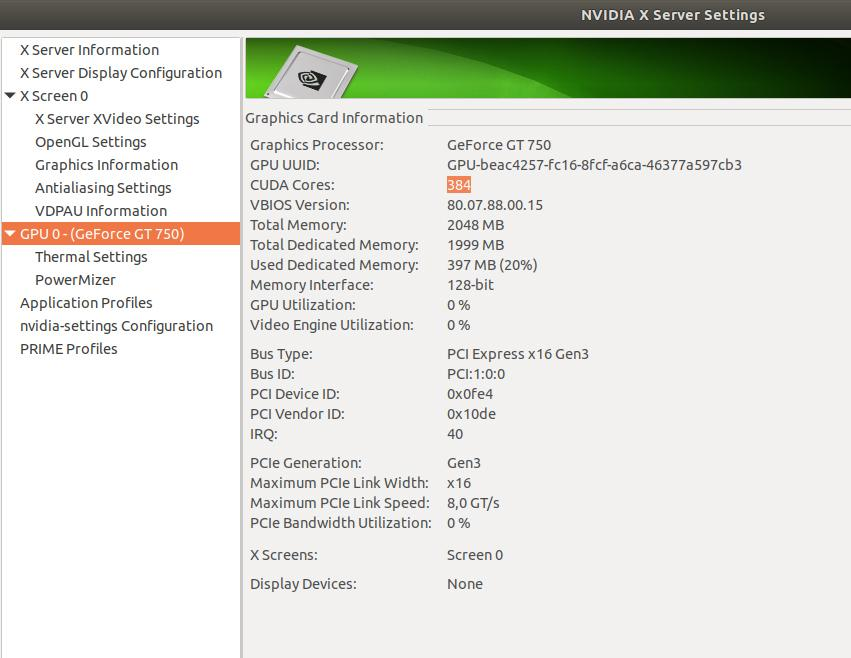

## Parallelizzazione di calcoli matriciali mediante l'utilizzo di `parfor` e `gpuArray`

### `parfor`

Matlab mette a disposizione il `Parallel Toolbox` per l'elaborazione parallela e ottimizzazione di problemi di calcolo.

Il `parfor `è uno degli strumenti messi a disposizione per ottenere i risultati precedentemente descritti; in particolare, si tratta di un'istruzione di controllo che permette l'esecuzione parallela di alcune operazioni all'interno di un ciclo `for`.

A titolo d' esempio, calcoleremo il prodotto matriciale di matrici generate casualmente di dimensione fissa. Il prodotto sarà effettuato un numero di volte crescente ad ogni iterazione, in modo da rendere lapalissiana la maggiore efficienza dell'elaborazione parallela per alcune operazioni.

Successivamente visualizzeremo e valuteremo l'andamento dei tempi di calcolo.

% Prodotto matrici in parallelo
niter = [500 1000 5000 10000];
dim   = 1000;
v     = rand(dim*dim,1);
m     = reshape(v, dim, dim);
 
% Esecuzione sequenziale
for k=1:length(niter)
    tic;
    for i=1:niter(k)
        prod=m*m;
    end
    time(1,k)=toc;
end

% Esecuzione parallela
for k=1:length(niter)
    tic;
    parfor i=1:niter(k)
        prod=m*m;
    end
    time(2,k) = toc;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


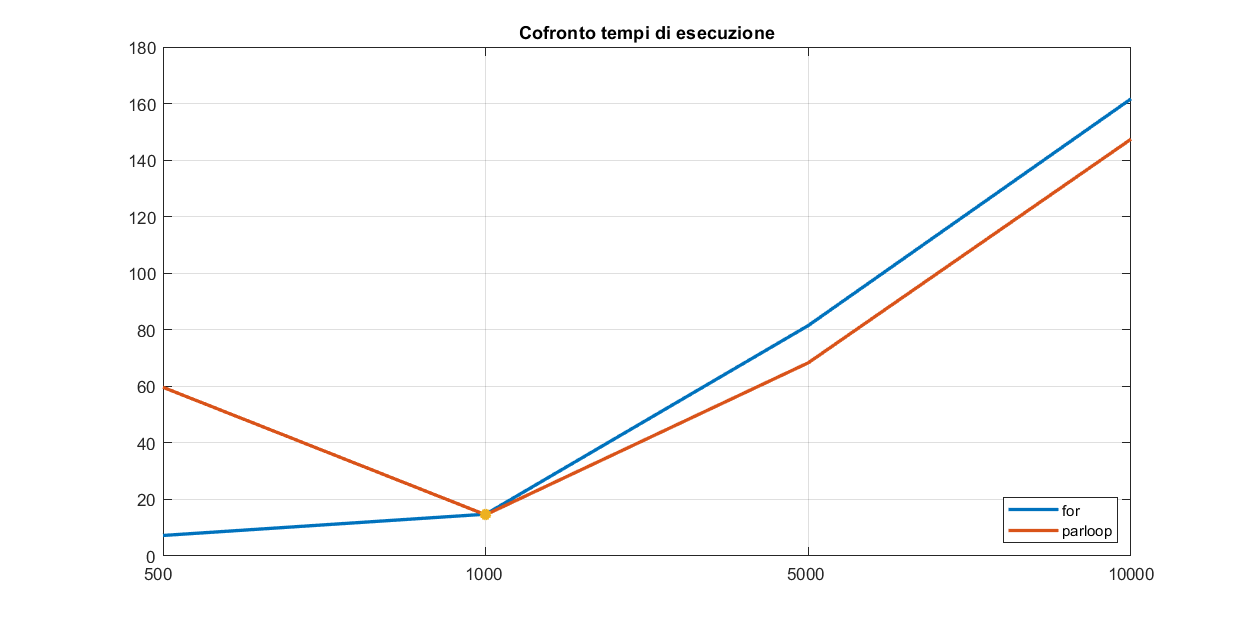

figure('Position', [250 250 1000 500])
plot(time.','LineWidth',2),title('Cofronto tempi di esecuzione'),hold on,grid on;
plot(2,14.58,'*','LineWidth',4)
legend('for','parloop','Location','southeast');
ax=gca;
ax.XTick=1:4;
ax.XTickLabel={niter};

Prestando attenzione all'andamento dei tempi di esecuzione, è interessante notare, come per poche iterazioni il tempo impiegato dall'elaborazione con il `parfor` è maggiore rispetto al caso in cui si utilizza il `for`**.** Questa "anomalia" è dovuta al tempo necessario per creare i worker, in modo da suddividere il lavoro ed unire i risultati. Superato il punto di crossover, dove le due curve si incontrano, il `parfor` grantisce, come era lecito aspettarsi, prestazoni migliori.

### `gpuArray`

Presentiamo ora un ulteriore costrutto per la parallelizzazione alternativo al parfor, il `gpuArray`. Mentre il `parfor` parallelizza l'esecuzione creando più workers ( parallelizzando l'esecuzione a livello CPU), `gpuArray` permette di memorizzare un intera matrice nella` GPU Nvidia `e di eseguire i calcoli utilizzando la `GPU` . 

Mettiamo ora a confronto i tempi di calcolo della `CPU` e della` GPU` nel caso in cui si effettuano delle operazioni che possono essere parallelizzate. 

Per l'esempio è stato scelto il calcolo di una versione modificata del `frattale di Julia, `per calcolare tale frattale è necessario eseguire nell'eseguire un numero elevato di operazioni su matrici di reali e numere immaginari :

maxIterations = 100;
gridSize = 2000;
xlim=0; ylim=0;
l=1.5;

% xGPU=gpuArray.linspace(xlim-l,xlim+l,gridSize);
% yGPU=gpuArray.linspace(ylim-l,ylim+l,gridSize);
% zGPU=zeros(gridSize,'gpuArray');

x=linspace(xlim-l,xlim+l,gridSize);
y=linspace(ylim-l,ylim+l,gridSize);
z=zeros(gridSize);

timeCPU = frattale(x, y, z, maxIterations)

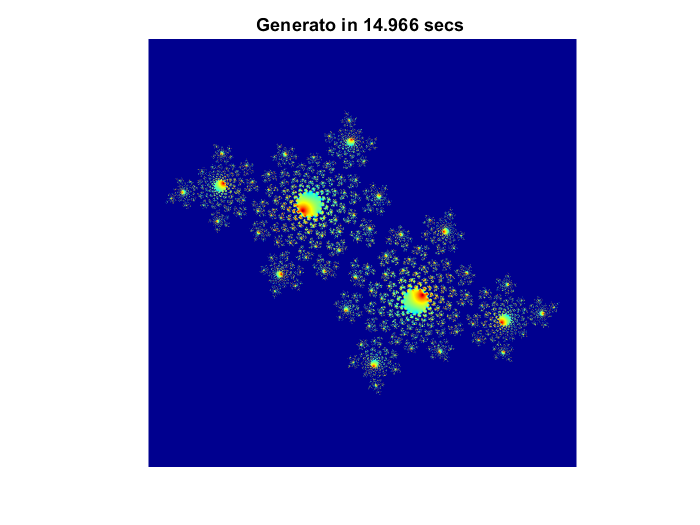

timeCPU = 14.9665

timeGPU = frattale(xGPU, yGPU, zGPU, maxIterations)

Come si può notare, l'utilizzo della `GPU` ha reso l'elaborazione del frattale notevolmente più veloce rispetto al caso in cui si utilizza la `CPU`.

## Deep learning e addestramento di reti neurali mediante l'utilizzo della tecnologia CUDA delle GPU Nvidia

In questa sezione, mostreremo come utilizzare Matlab e il **Deep Learning Toolbox **elaborare ed addestrare una rete neurale artificiale (ANN) convolutiva per la classificazione dei numeri compresi tra 0 e 9 scritti a mano.

A tal proposito, si è utilizzato uno, tra gli innumerevoli, *dataset* messi a disposizione dalla Matlab community. I dati in questione saranno suddivisi nell'insieme necessario per l'addestramento della *ANN *e nell'insieme necessario per la verifica. Lo scopo prefisso è la dimostrazione delle potenzialità del `Matlab`, il quale, nel modo più semplice, permette di utilizzare la **GPU **per eseguire operazioni parallelizzabili.

Tale risultato è ottenibile, e perseguibile, in virtù della natura del problema della classificazione nell'ambito dell'intelligenza artificiale: L'***Image classification*** è effettuata addestrando la ANN attraverso l'utilizzo di immagini alle quali è associata la corretta etichetta, che rappresenta il contenuto dell'immagine (nel nostro caso, le cifre decimali). Dopodiché, viene fornito un set di immagini da classificare per testare la rete. La classificazione viene effettuata attraverso un confronto, in modo da riconoscere il significato dell'imagine attraverso delle similitudini con quelle che già si conoscono; a tali immagini, saranno, poi, associati un' etichetta ed il relativo grado di confindenza (in punti percentuale).

Proprio il confronto di immagini, nella classificazione, puo' essere elaborato parallelamente utilizzando la **GPU.**

### Inizializzazione

In primo luogo, carichiamo il percorso delle cifre `(digitsPath)` e successivamente creiamo il datastore associato ad esso, necessario per caricare in memoria elementi che normalmente non potrebbero entrarvi a causa della dimensione elevata (*ndr *del *dataset*) [1].

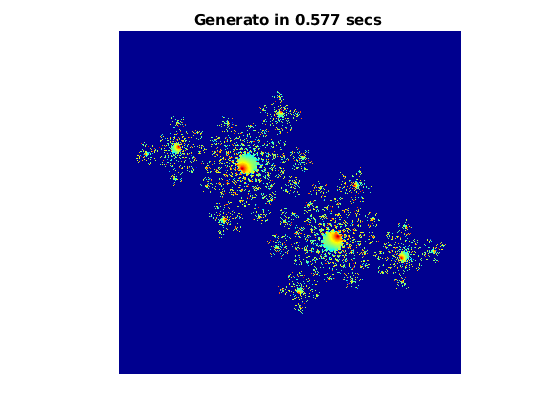

timeGPU = 0.5774

digitsPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...

    'nndatasets','DigitDataset');
imds = imageDatastore(digitsPath, 'IncludeSubfolders', true, ...
    'LabelSource','foldernames');

Di seguito, mostriamo alcune immagini del *dataset* utilizzato per l'apprendimento della rete in questione.

figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

Dividiamo, ora, il *dataset* in due insiemi distinti: training e validation. Il primo sarà utilizzato dalla rete come fonte di apprendimento, il secondo, invece, verrà sfruttato per testare il funzionamento della rete e verificare il grado di confidenza richiesto/minimo.

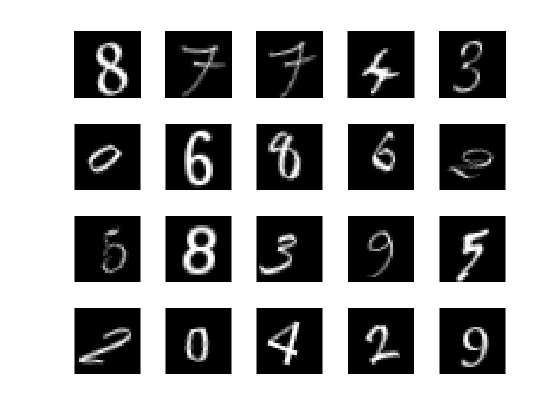

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

### Specifiche

#### Specifiche della rete

Ecco la definizione delle specifiche della rete che andremo ad addestrare. Per poter effettuare i calcoli, è necessario specificare sia il metodo di convoluzione che la dimensione del *dataset* fornito in ingresso.

layers = [
    % dimensione delle immagini (28x28x1, bw)
    imageInputLayer([28 28 1])
    
    % definizione delle proprietà della rete
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

#### Specifiche dell'apprendimento

Il passo successivo è la definizione delle specifiche riguardanti l'apprendimento della nostra ANN.

I parametri di interesse utilizzati sono:

-  `MaxEpochs:` numero di epoche, ovvero il numero di iterazioni totali sul *dataset*. Maggiore è il numero di epoche, maggiore sarà la precisione raggiunta, a discapito dell'efficienza.

- `Plots:` per mostrare graficamente l'apprendimento in tempo reale

- `ExecutionEnvironment:`  sarà utilizzato per specificare l' esecuzione dell' apprendimento sulla `CPU` o sulla `GPU`. 

Saranno addestrate due reti, una utilizzando la `CPU` e l'altra la `GPU`, per mostrare le differenze prestazionali.

% opzioni per il training su gpu
option_gpu = trainingOptions('sgdm', ...
    'InitialLearnRate',0.005, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu');
% opzioni per il training su cpu
option_cpu = trainingOptions('sgdm', ...
    'InitialLearnRate',0.005, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','cpu');

### Esecuzione del training

Eseguiamo ora il training, prima sulla `CPU` e poi sulla `GPU`. L' `accuracy` rappresenta la precisione della rete neurale, ed è evidente che maggiore è il numero di immagini del *dataset* analizzate (quindi più epoche attraversiamo, cioè "giri" di addestramento completi del *dataset*) più l'`accuracy` tende al 100%, a discapito del tempo di calcolo (efficienza).

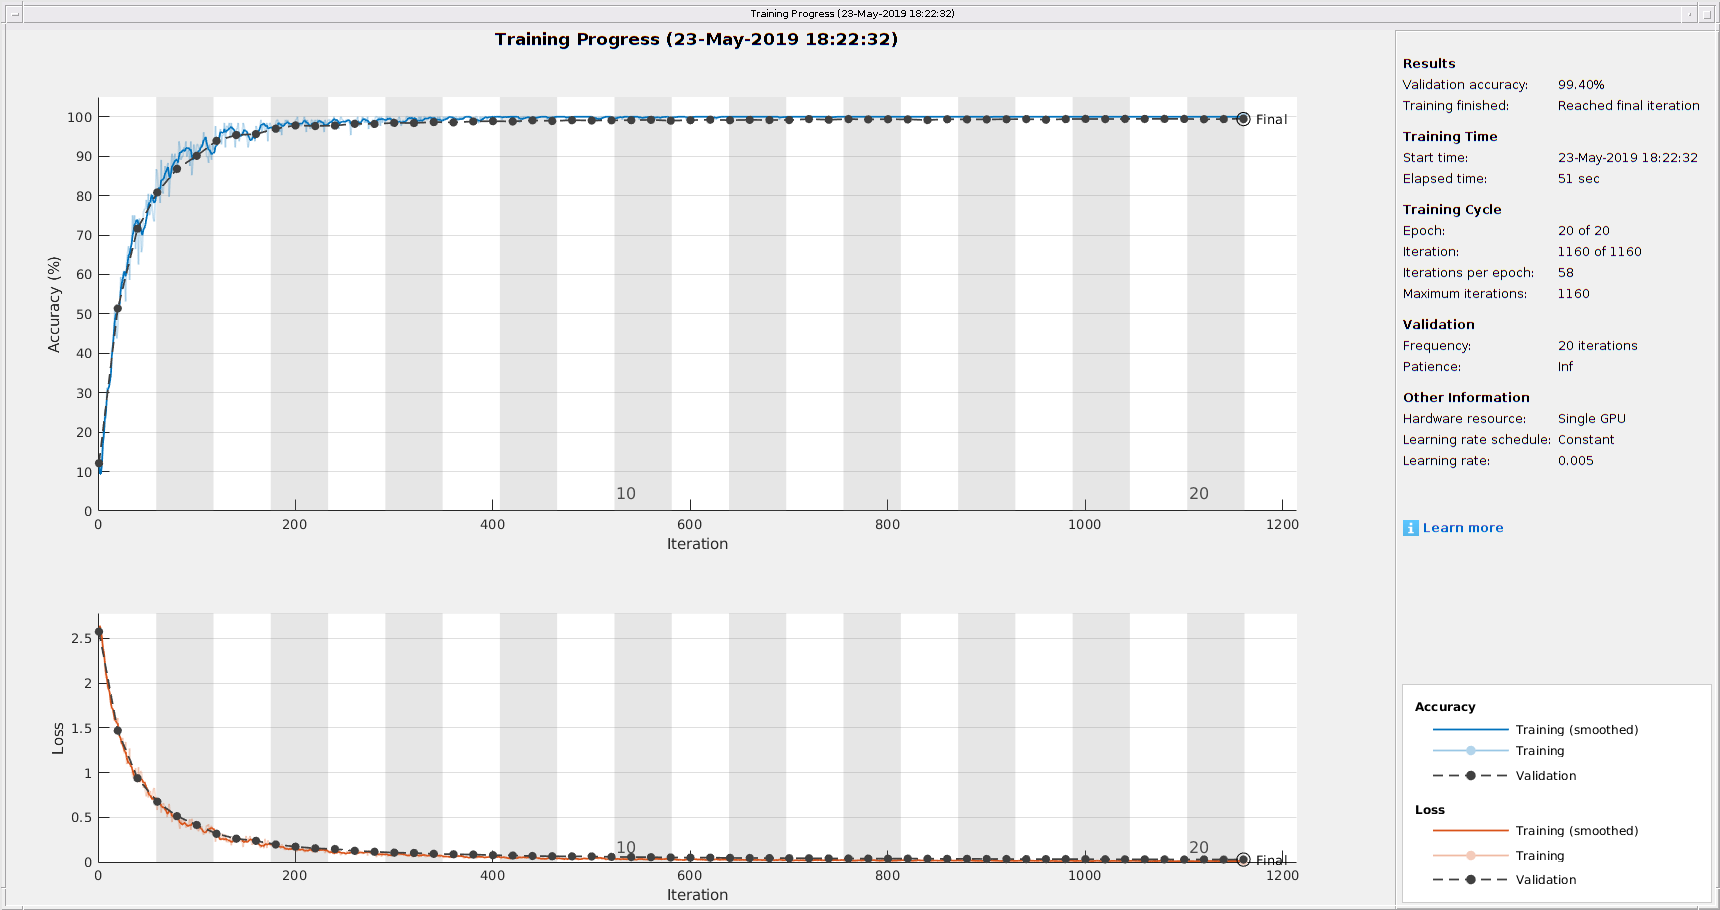

net_gpu = trainNetwork(imdsTrain,layers,option_gpu);

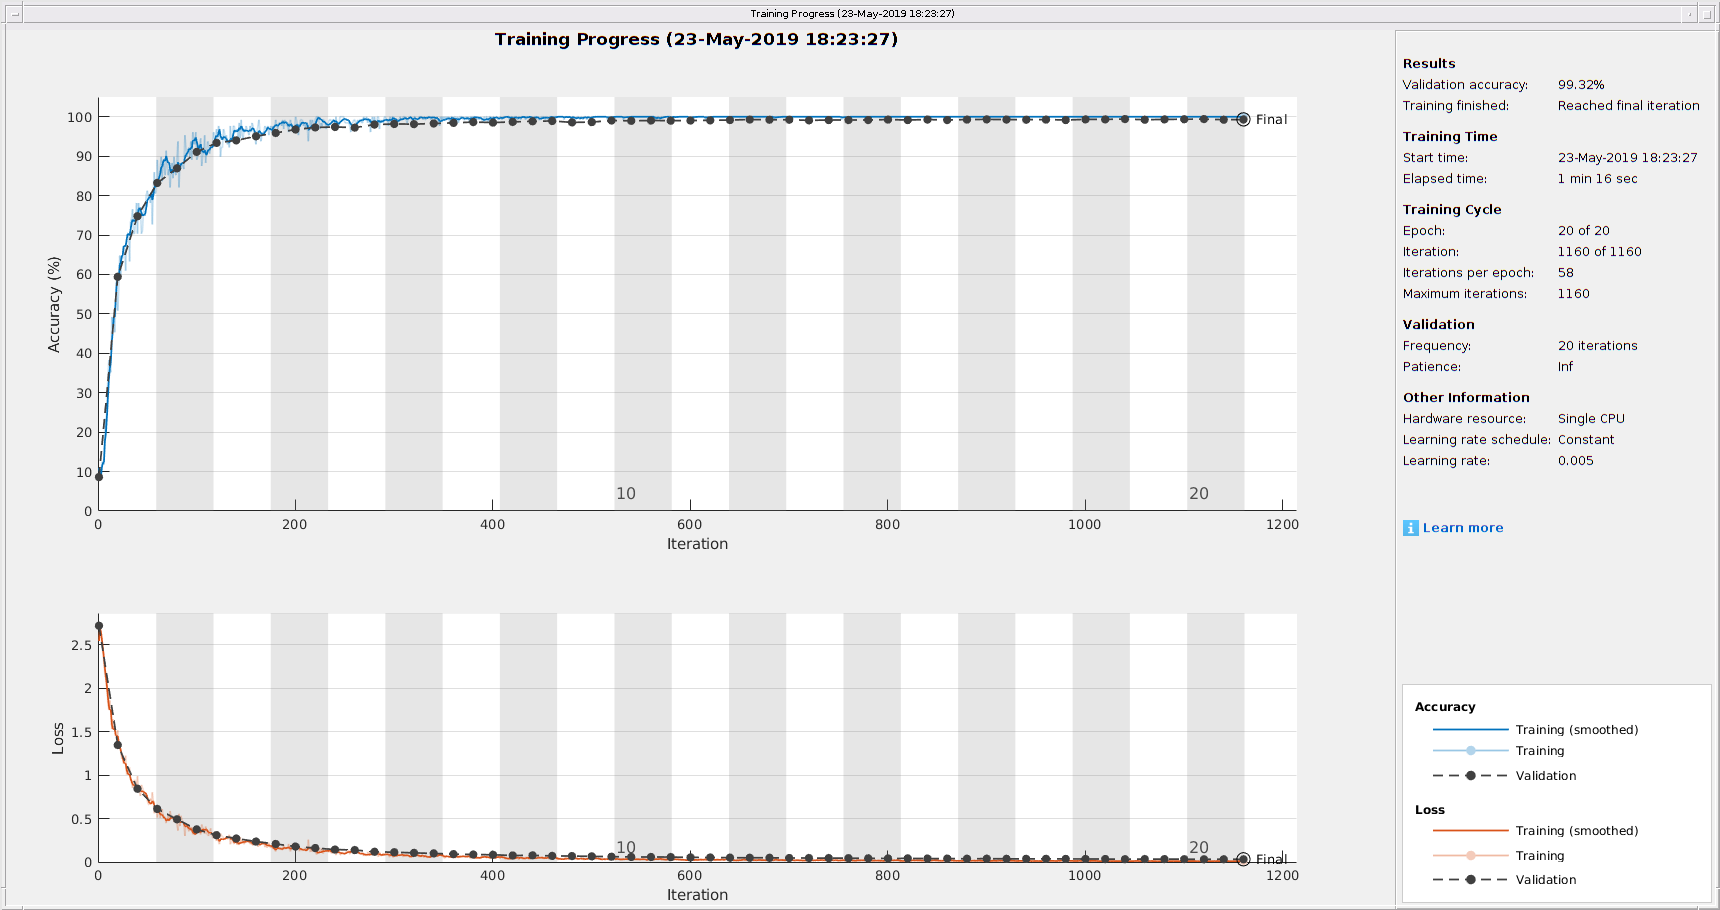

net_cpu = trainNetwork(imdsTrain,layers,option_cpu);

Entrambe le soluzioni, quella su `CPU` e quella su GPU, hanno prodotto un ottimo risultato: in effetti entrambe posseggono un' `accuracy` superiore al 99% per la validazione, il che significa che prese delle immagini dal *dataset* per la validazione, al termine dell'addestramento, la rete riesce a determinare il valore contenuto nell'immagine con una confidenza prossima al 100%.

Per quanto concerne la velocità di apprendimento della rete, nel caso in cui viene utilizzata un `GPU`, anche se la rete presa in esempio è di piccole dimensioni, è più veloce . In questo caso utilizzando la **GPU** il tempo impiegato è inferiore di circa il 60% rispetto a quello impiegato utilizzando la **CPU.** 

### Risultati del training

Per semplicità, poiché le due reti sono identiche (escluso l'ambiente di esecuzione, *ndr GPU/CPU*), utilizziamo solamente la rete addestrata utilizzando la GPU. 

Dopo l'addestramento, possiamo utilizzare il metodo `classify` per poter classificare gli elementi contenuti nel *validation set* e verificare se la predizione è corretta e con quale precisione:

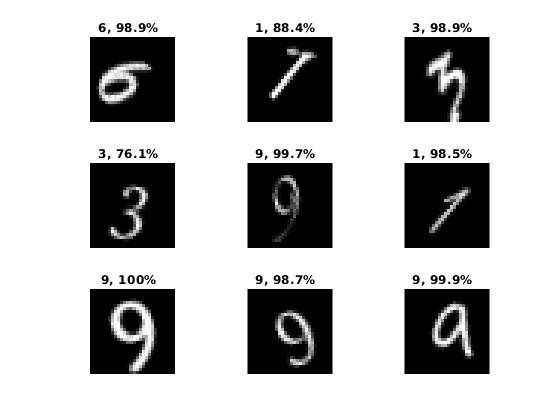

net = net_gpu;
[YPred,probs] = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
% accuracy della rete
accuracy = sum(YPred == YValidation)/numel(YValidation);

% Predizione del numero su immagini random 
figure
idx = randperm(2500,9);
for i = 1:numel(idx)
    subplot(3,3,i)
    imshow(imdsValidation.Files{idx(i)});
    prob = num2str(100*max(probs(idx(i),:)),3);
    predClass = char(YPred(idx(i)));
    title([predClass,', ',prob,'%  '])
end

## Riferimenti

[1] [Doc di imageDatastore](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html)

[2] [Deep Learning](https://it.mathworks.com/products/deep-learning.html)

## Autori

  Andrea Abbate, Gabriele Previtera, Cristiano Salerno